# Excel to PDF

This example shows how to create a PDF report from a Microsoft® Excel® spreadsheet by using MATLAB® Report Generator™. In this example, the Excel spreadsheet summarizes annual food imports by food category. The source of the spreadsheet is the Economic Research Service, U.S. Department of Agriculture. The spreadsheet is available at [U.S. Food Imports](https://catalog.data.gov/dataset/u-s-food-imports). The example uses a local copy of the spreadsheet.

## Import Excel Data

Import the data from the spreadsheet, `Alltables.xlsx`, into MATLAB® cell arrays.

xlsfile = "Alltables.xlsx";
years = readcell(xlsfile, "Sheet","FOOD$","Range","D2:V2");
data = readcell(xlsfile, "Sheet","FOOD$","Range","D7:V21");
types = readcell(xlsfile, "Sheet","FOOD$","Range","A7:A21");
units = readtable(xlsfile, "Sheet","FOOD$","Range","K3:K3","ReadVariableNames",false);

## Create a Report

Import the DOM and Report API packages so that you do not have to use long, fully-qualified class names.

import mlreportgen.report.*
import mlreportgen.dom.*

Create a container to hold the report content for a PDF report.

rpt = Report("Food Imports Report","pdf");

## Create the Title Page

Create and add a title page to the report.

tp = TitlePage();
tp.Title = "Food Imports Report Based on Multi-Year Data from the USDA";
tp.Image = "peppers.png";
tp.Author = "John Doe";
tp.PubDate = date;
add(rpt,tp);

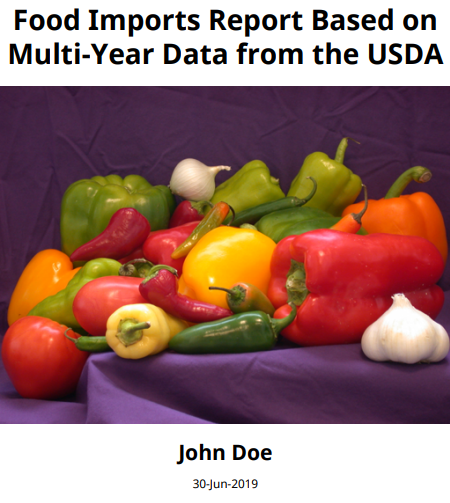

## Create the Table of Contents

Create and add a table of contents by using the `mlreportgen.report.TableofContents` reporter. This reporter automatically creates the table of contents based on the chapter and section titles in the report.

toc = TableOfContents();
add(rpt,toc);

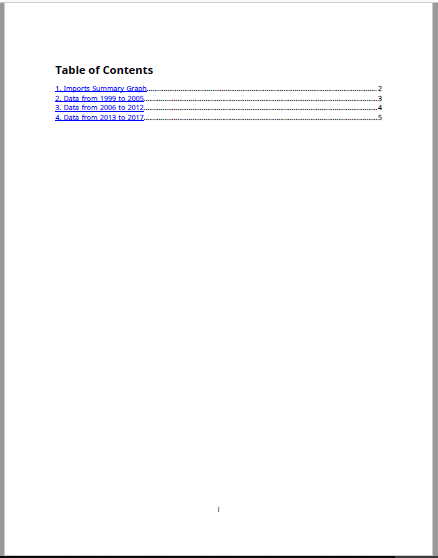

## Plot the Data in MATLAB

Create and format a line plot of the annual imports by food category.

fig = figure("Color","w");
ax = axes(fig,"FontSize",12);
t = str2double(years);
for i = 1:size(data,1)
    hold on;
    plot(ax,t,[data{i,:}],"LineWidth",1);
end
xlabel("Years");
ylabel(units.Var1{:});
legend(types,"Location","northeastoutside");
title("Food Imports");

## Add the Plot to the Report

Create a chapter and add the line plot to it.

ch = Chapter("Imports Summary Graph");
fig = Figure(fig);
add(ch,fig);
add(rpt,ch);

## Convert the Data to a Suitable Form for Creating a DOM Table

Format the data and create a single string array, `tableData`, that you can use to create an `mlreportgen.dom.Table` object.

tableData = cellfun(@(x)sprintf("%.0f",x),data);
tableData = [types tableData];
tableHeader = ["" string(years)];
tableData = [tableHeader; tableData]

## Create a Food Imports Table in the Report

Create an `mlreportgen.dom.Table` object from the food imports data in the `tableData` variable. Specify the table formats.

table = Table(tableData);
table.Style = { ...
    Border("solid"), ...
    RowSep("solid"), ...
    ColSep("solid"), ...
    OuterMargin("5pt","5pt","5pt","5pt")};
table.TableEntriesStyle = {InnerMargin("2pt")};

headerStyle = { ...
    BackgroundColor("LightBlue"), ...
    Bold };

table.row(1).Style = headerStyle;

grps = TableColSpecGroup;
grps.Span = 1;
grps.Style = headerStyle;
table.ColSpecGroups = grps;

## Fit the Table to the Report Page by Vertically Slicing

To fit a wide table on a report page, divide the table vertically into a set of narrower tables (slices), by using an `mlreportgen.utils.TableSlicer` object.

slicer = mlreportgen.utils.TableSlicer(...
    "Table",table, ... 
    "MaxCols",8, ...
    "RepeatCols",1);
slices = slicer.slice();

## Add Chapters for the Table Slices

Create a chapter for each table slice and add the chapters to the report.

for slice = slices
    ch = Chapter();
    ch.Title = strjoin(["Data from" years(slice.StartCol-1)...
        "to" years(slice.EndCol-1)]);
    add(ch,slice.Table);
    add(rpt,ch);
end

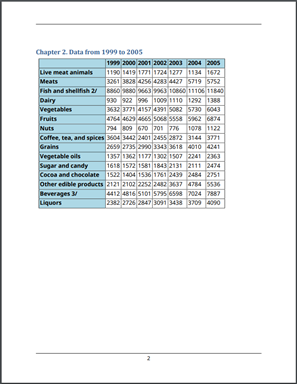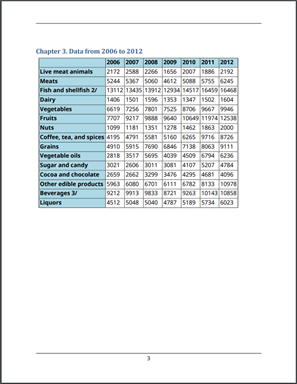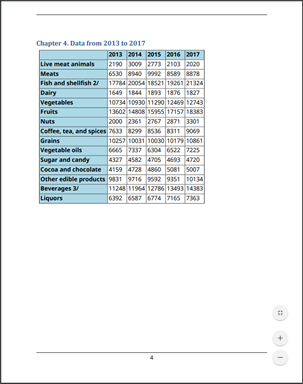

## Close and View the Report

close(rpt);
rptview(rpt)


*Copyright 2019 The MathWorks, Inc.*